# Introduction to Matlab

Live script is a script with editing capabilities. It combines MATLAB code with embedded output, formatted text, equations, and images in a single environment called the Live Editor. Live scripts are stored using the Live Script file format in a file with a `.mlx` extension.

## Cleaning

clear %Clearing memory
close all %Closing all graphs

## Simple Number Manipulations

4^2

ans = 16

2+5000

ans = 5002

## Matrices

Typing a matrix

A = [1,2,3 
     4,5,6] %The ; suppresses output

A =      1     2     3
     4     5     6


B = A'      %Transpose

B =      1     4
     2     5
     3     6


C = A*B     %Multiply (matrix size must conform)

C =     14    32
    32    77


A.*A        %Multiply element by element (for same size matrices)

ans =      1     4     9
    16    25    36


A./A

ans =      1     1     1
     1     1     1


B = B.^2    %Square each element

B =      1    16
     4    25
     9    36


inv_C = inv(C)   %inverse 

inv_C =     1.4259   -0.5926
   -0.5926    0.2593


A(2,1)      %Displays element(row,column)

ans = 4

A(1,end)    %Displays last element of row 1

ans = 3

A(end,2)    %Displays last element of column 2

ans = 5

A(:,2)=[]   %Deletes the 2nd column

A =      1     3
     4     6


A(1,:)=[]   %Deletes the 1st row

A =      4     6


## Special Matrices

C = rand(4,4) %Random draws from U[0,1]

C =     0.7943    0.6020    0.7482    0.9133
    0.3112    0.2630    0.4505    0.1524
    0.5285    0.6541    0.0838    0.8258
    0.1656    0.6892    0.2290    0.5383


D = ones(4,2) %Matrix of ones

D =      1     1
     1     1
     1     1
     1     1


E = zeros(2,4) %Matrix of zeros

E =      0     0     0     0
     0     0     0     0


F = eye(3,3) %Identity matrix

F =      1     0     0
     0     1     0
     0     0     1


G = randn(3,2) %Random draws from N(0,1)

G =     1.4367   -1.2078
   -1.9609    2.9080
   -0.1977    0.8252


## Important Functions for Data Work

min_G = min(G) %min element in each column. Also see max, mean

min_G =    -1.9609   -1.2078


sum_G = sum(G) %sum of elements in each column.

sum_G =    -0.7219    2.5254


cumsum_G = cumsum(G) %each row element = cumulative sum of prev. row entries

cumsum_G =     1.4367   -1.2078
   -0.5242    1.7002
   -0.7219    2.5254


% within column


## Grids and Arrays

x = 1:2:10 %Creates a vector with value difference of 2

x =      1     3     5     7     9


x = [3, 12, 0; 7, 11, 13; 6, 6, 6] %Manually enter matrix values

x =      3    12     0
     7    11    13
     6     6     6


x = linspace(1,3,6)' %n equally spaced numbers between a and b

x =     1.0000
    1.4000
    1.8000
    2.2000
    2.6000
    3.0000


## Basic graphs

Plotting $y=x^2$.

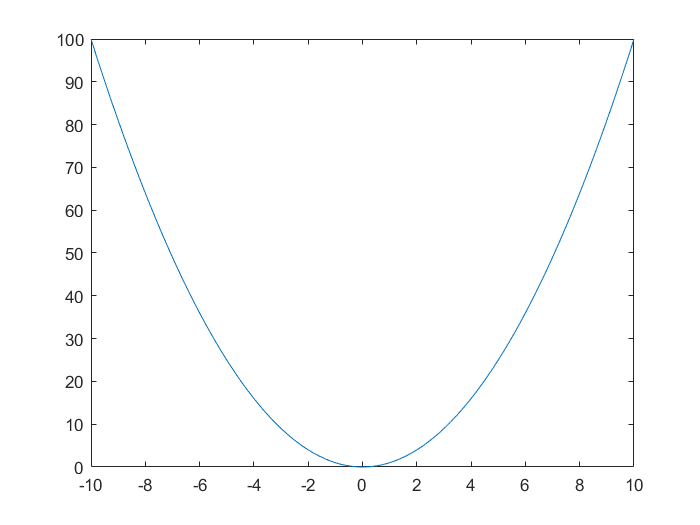

x=linspace(-10,10,101); %Grid of 101 equally spaced points from -10 to 10
y=x.^2; %y-values. The .^ power is element-by-element power
plot(x,y) %Plot line graph

## Customizing graphs

Plotting $y=x^3$, and adding title, axis labels, modifying properties.

Find Matlab color codes at: [Matlab Colors](http://shirt-ediss.me/matlab-octave-more-colours/)

x=linspace(-10,10,101); %Grid of 101 equally spaced points from -10 to 10
y=x.^3; %y-values. The .^ power is element-by-element power.
figure('Name','Customized plot');
p = plot(x,y,'Color','k', 'LineWidth',5, 'LineStyle', '-.') %Plot line graph. p stores the line properties, e.g. 'Color', 'LineWidth'. 

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


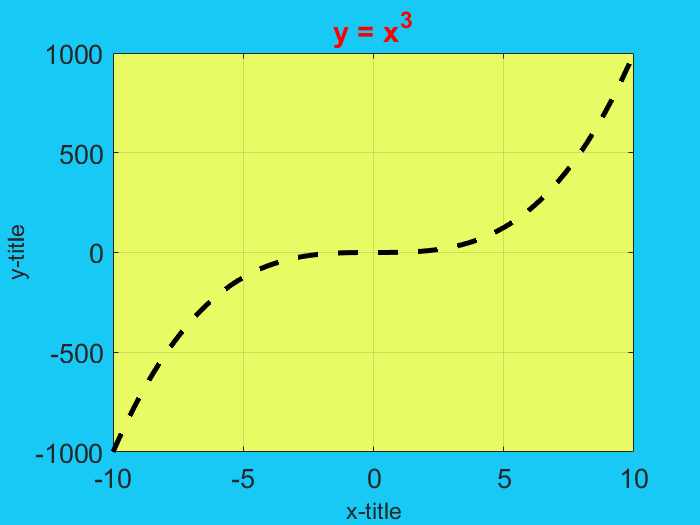

set(p,'Color','k', 'LineWidth',3, 'LineStyle', '--') %Setting line color and width. 
set(gcf,'Color', [24 200 245] ./ 255) %Frame color
set(gca, 'FontSize',16, 'Color',[232 251 100] ./ 255) %Axis fontsize and plot background color.
title('y = x^3','FontSize',16,'Color','red') %Title fontsize.
xlabel('x-title','FontSize',14)
ylabel('y-title','FontSize',14,'Rotation',90) %Rotation is optional. Default is 90 degrees.  
grid on %Adding gridlines

help graph

 graph Undirected Graph
    G = graph builds an empty graph with no nodes and no edges.
 
    G = graph(A) uses the square symmetric matrix A as an adjacency matrix
    and constructs a weighted graph with edges corresponding to the nonzero
    entries of A. The weights of the edges are taken to be the nonzero
    values in A. If A is logical then no weights are added.
 
    G = graph(A,NAMES) additionally uses NAMES as the names of 
    the nodes in G. NAMES must be a string vector or a cell array of
    character vectors, and must have as many elements as size(A,1).
 
    G = graph(A,...,TYPE) uses only a triangle of A to construct the graph.
    TYPE can be:
            'upper'  -  Use the upper triangle of A.
            'lower'  -  Use the lower triangle of A.
 
    G = graph(A,...,'omitselfloops') ignores the diagonal entries of the
    adjacency matrix A and does not add self-lo